*Use the Live Editor to ****edit**** and ****run**** this live script in your browser or *[*download*](https://www.mathworks.com/live_editor_exploringexoplanets)* and run it in your MATLAB.*

## 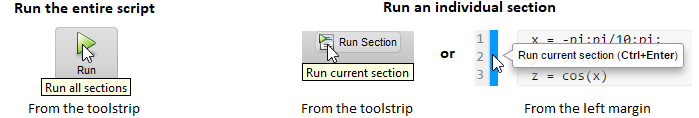

***Challenge:**** Can you use the debugger to explore the execution of the *`plot_star_types`* function?*

# Exploring Exoplanets

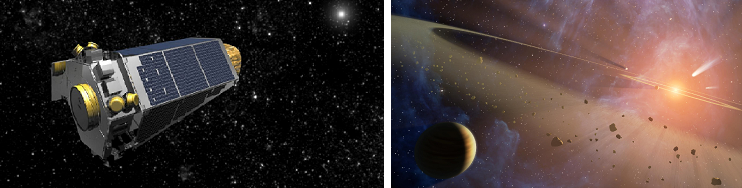

In this example we will explore some data on exoplanets - planets outside our own solar system.  The data used here is a subset of data from the [NASA Exoplanet Archive](http://exoplanetarchive.ipac.caltech.edu/).

We will start by using the data to answer some questions about the set of exoplanets in the archive.  Then we will do some calculations to try to identify planets in the archive that might be capable of supporting life.

exoplanets = readtable('exoplanets.xlsx','TextType','string');
exoplanets(1:8,:)

ans = 8×16 table
            st_name            st_distance    st_right_ascension    st_declination    st_spectral_type    st_solar_radii    st_mass    st_luminosity    st_effective_temp    pl_discovery_method    pl_orbital_period    pl_orbital_sm_axis    pl_orbital_eccentricity    pl_orbital_inclination    pl_earth_mass    pl_earth_radii
    _______________________    ___________    __________________    ______________    ________________    ______________    _______    _____________    _________________    ___________________    _____________

## How Far Away Are these Planets?

There are 90 exoplanets within 50 light-years of earth and 450 exoplanets within 200 light-years.

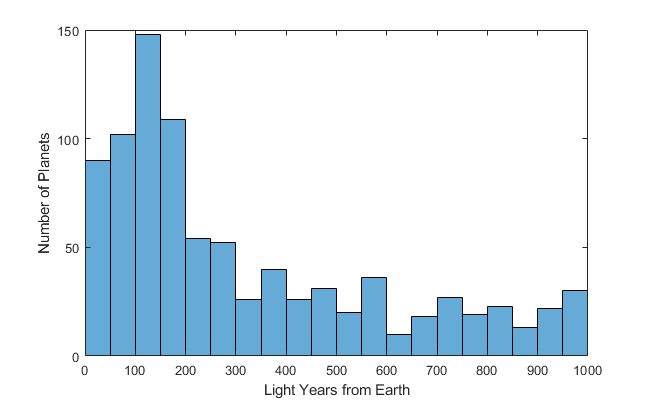

bigFigure
histogram(3.26*exoplanets.st_distance,'BinWidth', 50)
xlim([0 1000])
ylabel 'Number of Planets'
xlabel 'Light Years from Earth'

Where is the nearest exoplanet?

idx = find(exoplanets.st_distance == min(exoplanets.st_distance),1);
name = char(exoplanets{idx,'st_name'}) ;
dist = 3.26*exoplanets{idx, 'st_distance'};
fprintf('The nearest exoplanet is at %s, %4.2f light years away\n', name, dist)

The nearest exoplanet is at Proxima Cen, 4.21 light years away


## What Types of Stars have Planets?

We can look at the exoplanet archive to see what types of stars have been found to have at least one exoplanet.  The exoplanet archive has information about the host star's spectral type for about 940 of the 3400 entries.  We can get a sense of the distribution of star types from a scatter plot.  G-types stars like our sun are shown in yellow.

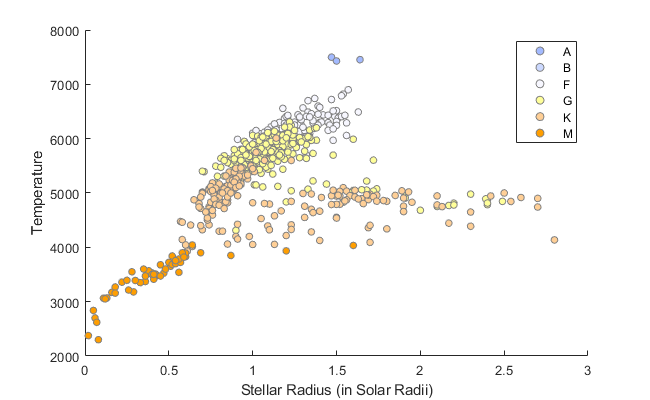

star_types = {'A' 'B' 'F' 'G' 'K' 'M'};
star_colors = [0.64 0.73 1.00; 0.80 0.85 1.00; 0.97 0.97 1.00; ...
    1.00 1.00 0.6; 1.00 0.81 0.59; 1.00 0.62 0.00];
T = exoplanets(~cellfun(@isempty, exoplanets.st_spectral_type),:);
data = {};
for i = 1:numel(star_types)
    data{i} = T(startsWith(T.st_spectral_type, star_types{i}), :);
end
plot_star_types(data, star_types, star_colors)

## What Methods are Used to Discover Exoplanets?

Astronomers use various methods to identify exoplanets.  Most exoplanets have been discovered using either through the [transit photometry](https://en.wikipedia.org/wiki/Methods_of_detecting_exoplanets#Transit_photometry) method or the [radial velocity](https://en.wikipedia.org/wiki/Methods_of_detecting_exoplanets#Radial_velocity) method but there are other methods as well.

byMethod = groupsummary(exoplanets,'pl_discovery_method');
byMethod = sortrows(byMethod,'GroupCount','descend')

byMethod = 8×2 table
          pl_discovery_method          GroupCount
    _______________________________    __________

    "Transit"                             2694   
    "Radial Velocity"                      620   
    "Imaging"                               44   
    "Microlensing"                          44   
    "Transit Timing Variations"             15   
    "Eclipse Timing Variations"              8   
    "Orbital Brightness Modulation"          6   
    "Pulsar Timing"                          5   


We can see the characteristics of the planets found by the top four methods above.

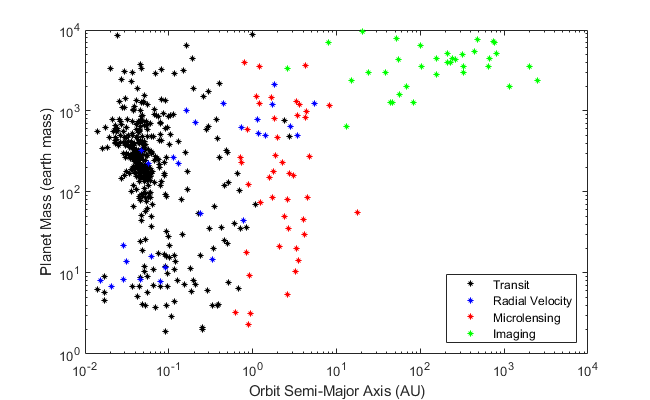

methods = {'Transit' 'Radial Velocity' 'Microlensing' 'Imaging'};
colors = {'black' 'blue' 'red' 'green'};
data = {};
for i = 1:numel(methods)
    data{i} = exoplanets(exoplanets.pl_discovery_method == methods{i},:);
end
plot_discoveries(data, methods, colors)

It looks like planets found by direct imaging of reflected light are large planets far from their host star.  Microlensing seems to work well for large, outer planets like Jupiter which are 6-10 AU from their parent star.  The transit and radial velocity methods work well for planets near their host stars and the transit method has been able to detect planets that are near earth size.

## Are Any of these Planets Habitable?

When we ask this question what we really mean is can these planets potentially support life?  That's a complicated question that invoves a lot of factors including

- Is the planet warm enought to have liquid water on it's surface?

- Is it a rocky planet like earth?

- Does it have a molten core?

- Does it have an atmosphere and what is it's composition?

- Is it subject to lethal radiation from its host star?

- etc.

Astronomers don't currently have instruments sensitive enough to answer most of these questions.  However, we can get a rough idea about whether a planet is habitable by looking at the first two criteria.  If the planet's temperature is between $0^\circ C$ and $100^\circ C$then liquid water can exist there.  If the planet's radius is close to that of earth we can assume that it is probably a rocky planet like earth and not a gas giant like Jupiter.

## Calculating a Planet's Temperature

So how do we calculate a planet's temperature?   We start by using the [Stefan-Boltzmann equation](https://en.wikipedia.org/wiki/Stefan%E2%80%93Boltzmann_law) to determine the star's energy output per unit area.


$$F_{\text{s}} =\sigma T_s^4$$


where $\sigma$is the Stefan-Boltzmann constant ($5\ldotp 67\text{ }x\text{ }{10}^{-8} \text{ }J\text{ }s^{-1} \text{ }m^{-2} \text{ }K^{-4}$) and $T_s$ is the temperature of the star.  Multiplying by the star's surface area gives the star's luminosity (total energy output) in watts.


$$L_s =4\pi R_s^2 \sigma T_s^4$$


With the star's luminosity and the distance of the planet from the star, we can figure out how much energy the surface of the planet receives from the star.


$$F_p =\frac{L}{4\pi a^2 }$$


where *a* is the planet's semi-major axis.  Note that we have assumed a circular orbit so the semi-major axis is the same as the orbital distance.  The value $F_p$ is the amount of energy reaching the planet per unit area.  The light gathering area of the planet can be approximated by its cross-sectional area.  Then the total energy reaching the planet can be calculated as


$$E_p =\text{ }\pi R_p^2 F_p$$


where $R_p$ is the planet's radius.  We know that the planet must be in thermal equilibrium -- not getter hotter or colder over time.  The planet radiates energy into space at the same rate it receives it from its star. The temperature at thermal equilibrium is called the [equilibrium temperature](https://en.wikipedia.org/wiki/Planetary_equilibrium_temperature).  We can use the same equation we used above to calculate the star's luminosity but this time using the planet's total energy input.


$$E_p =4\pi R_p^2 \sigma T_p^4$$


where $T_p$ is the planet's equilibrium temperature.  Rearranging for $T_p$ gives


$$T_p =\text{ }\sqrt[4]{\frac{E_p }{4\pi R_p^2 \sigma }}$$


## Calculating Equilibrium Temperatures and finding Habitable Planets

From the equations above, we need to know the star's temperature ($T_s$), the star's radius ($R_s$), the planet's orbital distance ($a$), and the planet's radius ($R_p$) to calculate the planet's equilibrium temperature.  We will create a candidate list of planets which have data for each of these values.  

candidates = rmmissing(exoplanets, 'DataVariables', ...
    {'st_solar_radii' 'st_effective_temp' 'pl_earth_radii' ...
    'pl_orbital_sm_axis'}) ;

sigma = 5.67e-8;                             % J/(s m^2 K^4)
R_earth = 6.371e6;
R_solar = 6.957e8 ;
AU = 1.496e11;

T_s = candidates.st_effective_temp;          % star temperature
R_s = R_solar*candidates.st_solar_radii;     % star radius
a   = AU*candidates.pl_orbital_sm_axis;      % planet orbital distance
R_p = R_earth*candidates.pl_earth_radii;     % planet radius

L_s = 4*pi*R_s.^2.*sigma.*T_s.^4;            % star luminosity
F_p = L_s./(4*pi*(a.^2));                    % planet energy per unit area
E_p = pi*R_p.^2.*F_p;                        % planet total energy from star

T_p = (E_p./(4*pi*R_p.^2.*sigma)).^0.25;     % planet equilibrium temperature

Now that we have an equilibrium temperature for the candidate list of planets, we can apply the liquid water and size requirements to see how many planets fit those criteria.

minTemp = 273;
maxTemp = 373;
max_earth_radii = 2.5;
habitable = candidates(T_p > 273 & T_p < 373 & ...
    candidates.pl_earth_radii < max_earth_radii,:)

habitable = 24×16 table
      st_name       st_distance    st_right_ascension    st_declination    st_spectral_type    st_solar_radii    st_mass    st_luminosity    st_effective_temp    pl_discovery_method    pl_orbital_period    pl_orbital_sm_axis    pl_orbital_eccentricity    pl_orbital_inclination    pl_earth_mass    pl_earth_radii
    ____________    ___________    __________________    ______________    ________________    ______________    _______    _____________    _________________    ___________________    _________________  

We can see how many of these planets are "close" to us.  We'll use a distance of <= 200 light-years.

max_distance = 200;
close = habitable(3.26*habitable.st_distance < max_distance,:)

close = 3×16 table
      st_name       st_distance    st_right_ascension    st_declination    st_spectral_type    st_solar_radii    st_mass    st_luminosity    st_effective_temp    pl_discovery_method    pl_orbital_period    pl_orbital_sm_axis    pl_orbital_eccentricity    pl_orbital_inclination    pl_earth_mass    pl_earth_radii
    ____________    ___________    __________________    ______________    ________________    ______________    _______    _____________    _________________    ___________________    _________________    

It looks like there are at least three potentially habitable exoplanets that are (relatively) close to earth.  Interesting, all three of these planets orbit dwarf red stars.

## **Attribution**

This research has made use of the [NASA Exoplanet Archive](http://exoplanetarchive.ipac.caltech.edu/), which is operated by the California Institute of Technology, under contract with the National Aeronautics and Space Administration under the Exoplanet Exploration Program.  

The data used here is a subset of the data from the archive with variable names updated for clarity.

## Local Functions

function f = bigFigure
figure('Position', [680 678 650 400]);
end


function plot_star_types(data, names, colors)

bigFigure
sc = gobjects(6,1) ;
for i = 1:numel(data)
    sc(i) = scatter(data{i}.st_mass, data{i}.st_effective_temp, 25);
    sc(i).MarkerFaceColor = colors(i,:) ;
    sc(i).MarkerEdgeColor = [0.5 0.5 0.5] ;
    hold on
end

hold off
ylim([2000 8000]) ; xlim([0 3])
xlabel('Stellar Radius (in Solar Radii)')
ylabel('Temperature')
legend(sc, names)

end


function plot_discoveries(data, names, colors)

bigFigure
for i = 1:numel(data)
    loglog(data{i}.pl_orbital_sm_axis, data{i}.pl_earth_mass, 'Marker' ,'*', ...
        'MarkerSize', 4, 'LineStyle', 'none', 'MarkerEdgeColor', colors{i})
    hold on
end

hold off
xlim([1e-2 1e4]) ; ylim([1e0 1e4])
legend(names, 'Location', 'Southeast')
xlabel('Orbit Semi-Major Axis (AU)')
ylabel('Planet Mass (earth mass)')

end